format shortg
clear all

# Oppgave 1

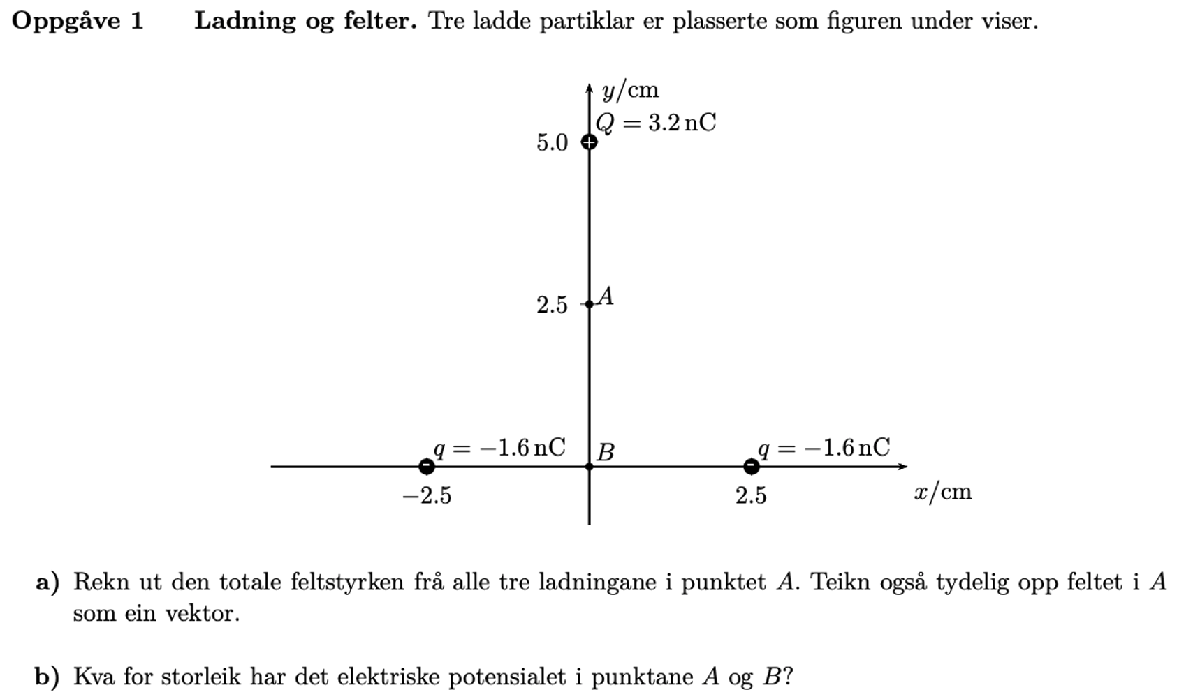

q1 = 3.2 * 10^-9;
q2 = -1.6 * 10^-9;
q3 = -1.6 * 10^-9;

a)

Finner feltstyrker fra hver ladning i A og adderer de.

r1A = (5-2.5) * 10^-2;
r2A = sqrt((-2.5)^2 + 2.5^2) * 10^-2;
r3A = sqrt(2.5^2 + 2.5^2) * 10^-2;

E1 = ElektriskFeltstyrkeFraPunktladning(0, q1, r1A);
E2 = ElektriskFeltstyrkeFraPunktladning(0, q2, r2A) %* cosd(45);

E2 =         11504


ElektriskFeltstyrkeFraPunktladning(E2, q2, 0)

ans =      0.035355


E3 = ElektriskFeltstyrkeFraPunktladning(0, q3, r3A) * cosd(45);
E = E1 + E2 + E3

E =         65655


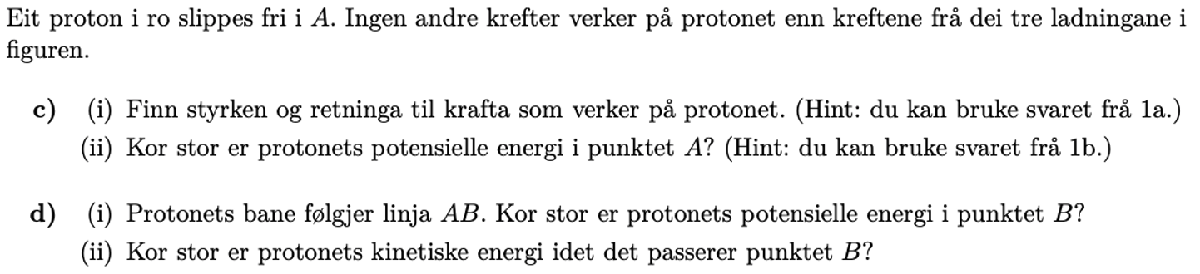

# Oppgave 2

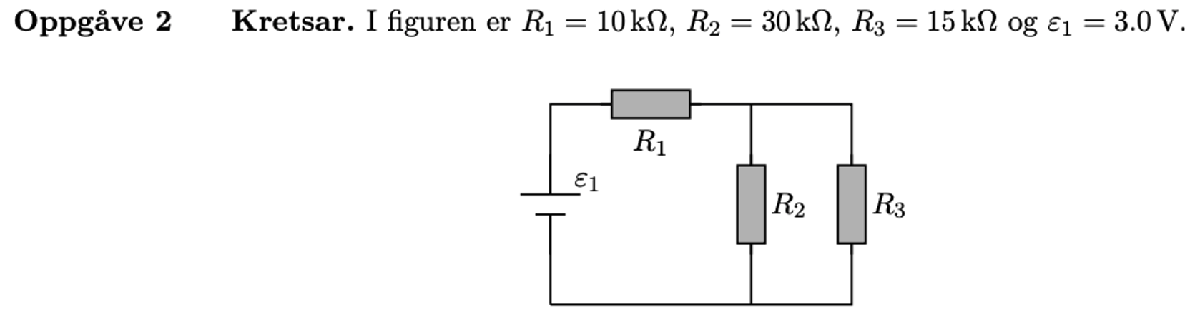

R_1 = 10 * 10^3; % Ohm
R_2 = 30 * 10^3; % Ohm
R_3 = 15 * 10^3; % Ohm
e_1 = 3.0; % Volt

R_23 = 1/((1/R_2)+(1/R_3));
R_eff = R_1 + R_23;
R_eff = R_ser([R_1 R_par([R_2 R_3])])

R_eff =        20000


fprintf('Den effektive motstanden i kresten er R_eff = %g Ohm', signif(R_eff, 2))

Den effektive motstanden i kresten er R_eff = 20000 Ohm

I_1 = ohms_lov(e_1, R_eff, 0)

I_1 =       0.00015


V_1 = R_1 * I_1

V_1 =           1.5


Spenningen over $R_2$og $R_3$er lik ettersomd e er paralellkoblet:

V_23 = e_1 - V_1

V_23 =           1.5


I_2 = V_23/R_2;
I_3 = V_23/R_3;
fprintf('I_1 = %g Ampere\nI_2 = %g Ampere\nI_3 = %g Ampere',signif(I_1, 2),signif(I_2, 2),signif(I_3, 2))

I_1 = 0.00015 Ampere
I_2 = 5e-05 Ampere
I_3 = 0.0001 Ampere

I serie med $R_3$

Parallellkoblet

Didoden ser slik ut: |< Hvor pilen angir hvilken retning strømmen skal gå, i denne kretsen med batteriet koblet med positiv pol oppover må atså dioden plasseres med pilen nedover.

# Oppgave 3

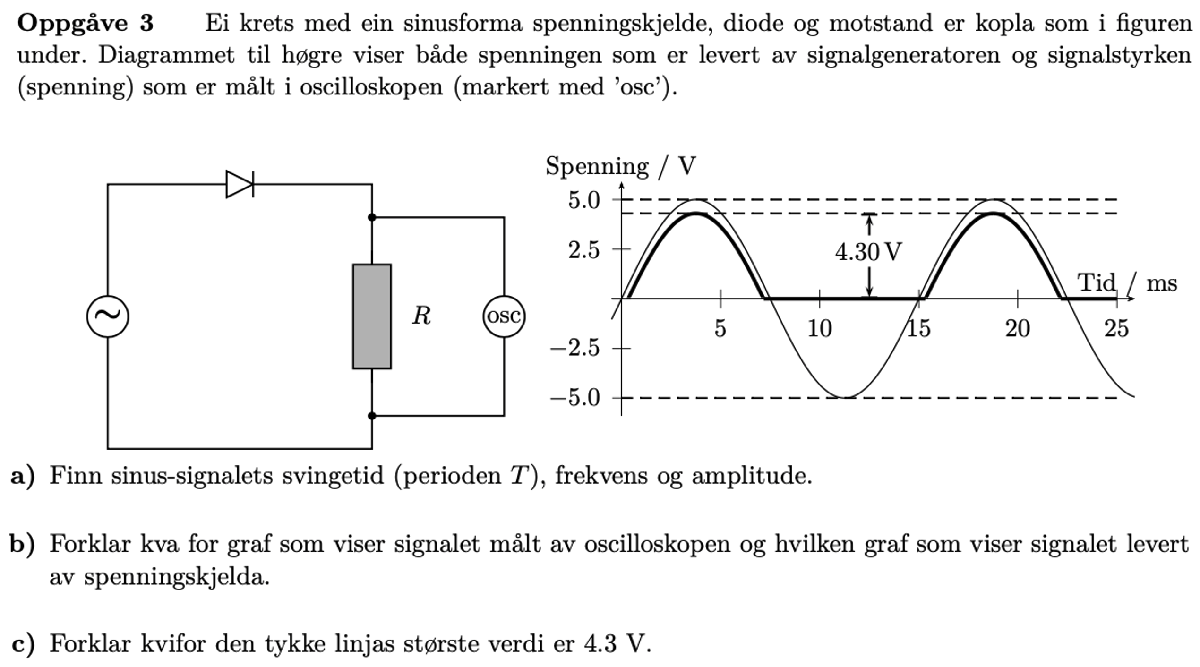

a) 

ser ut som tiden mellom hver topp er ca

svingetid = 15 *10^-3; % sekunder
Frekvens = 1/svingetid % Hertz

Frekvens =        66.667


Amplitude = 5; % Volt

b)

tjukk er målt, tynn er faktiske signalet.

c)

Fordi dioden som sannsynligvis har driftspenning på 0,7 V gjør at den makismale spenningen gjennom oscilloskopet er 5V (høyeste fra kilden) minus dioden. dette kommer av kirchoss 2. lov. forklarer også hvorfor den tjukke ikke har negative verdier ettersom dioden blokker signaler som går ene veien.